close all
clear variables

% Definición de las constantes del sistema
k = 1;     % Constante del resorte (N/m)
m = 1;      % Masa (kg)
b = 0.0;
x0 = 0;   % Posición inicial de la masa (m)
v0 = 1;     % Velocidad inicial de la masa (m/s)
Ts = 0.001;

A = [0 1; -k/m -b/m];
B = [0 1/m]';
C = eye(2);
D = 0;

sys = ss(A,B,C,D);

% Definición de la función que describe el sistema
fun_sys = @(x, u) A*x + B*u;

% Definición del tiempo de simulación
tspan = 0:Ts:50;

% Definición de las condiciones iniciales
x0 = [x0; v0];
u = 0;
% Solución de la ecuación diferencial
[t, x] = ode45(@(t,x) fun_sys(x, u), tspan, x0);

p = -m*x(:,2);
q = x(:,1);

% Parámetros del ruido
mu = 0;         % media
sigma = 0.06;    % desviación estándar

% Generar ruido gaussiano
noise_q = mu + sigma * randn(size(q));
noise_p = mu + sigma * randn(size(p));

q_noisy = q + noise_q;
p_noisy = p + noise_p;

### Graficas

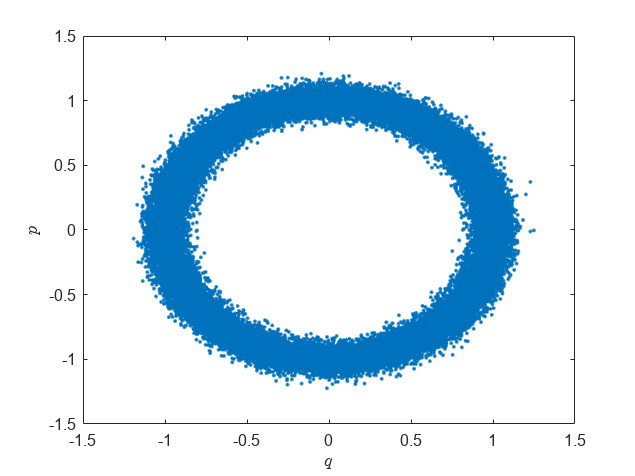

figure()
plot(p_noisy,q_noisy, '.')
xlabel('$q$', 'Interpreter','latex')
ylabel('$p$', 'Interpreter','latex')

Derivada momentum

dq = diff(q)/Ts + q_noisy(1:end-1);
dp = diff(p)/Ts + p_noisy(1:end-1);

Ruido

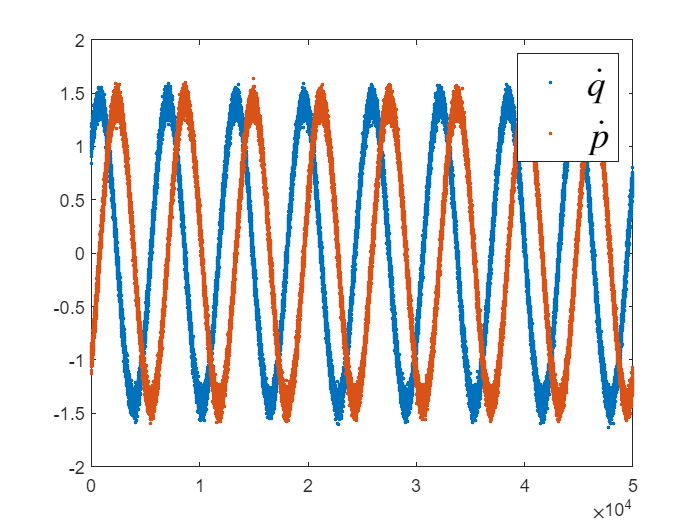

figure
plot(dq, '.')
hold on
plot(dp, '.')
hold off
legend('$\dot{q}$', '$\dot{p}$', 'Interpreter','latex', 'FontSize', 20)

Guardar datos

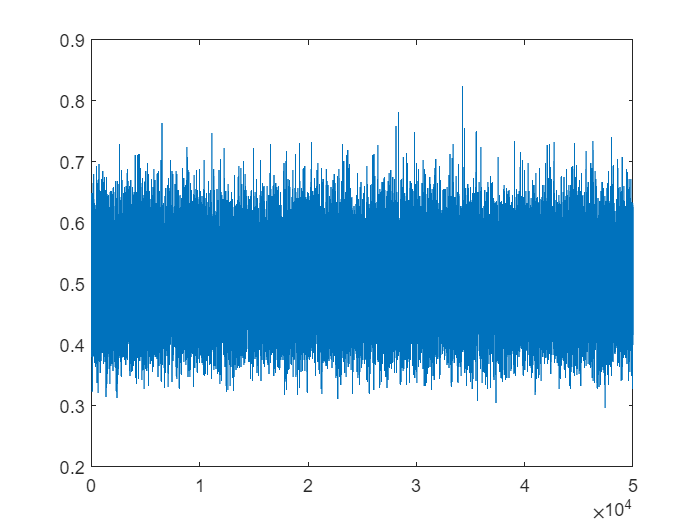

H = (k*q_noisy.^2)/2 + m*p_noisy.^2/2;
H = H(1:end-1);
plot(H)

input = [p_noisy, q_noisy];
output = H;
p = p_noisy(1:end-1);
q = q_noisy(1:end-1);
save('mass_spring','input', 'p','q','dp','dq', 'output')